% prep
clearvars -except kg kg2 rkg hkg k 
userfilespec = 'Eigen*';
numstart = 23;
daycount = 0;

## Go through entire data sample

## SET UP

tempchan = 3; % Either 4 or 3
lightchan = 4; % Either 5 or 4

% Get the list of files to be analyzed  
        iFiles = dir(userfilespec);
        
        datasubset = 6638:8170;
        
        iFiles = iFiles(datasubset);
            % Get sample frequency
            load(iFiles(1).name, 'tim');
            Fs = 1 / (tim(2) - tim(1));
            clear tim
               
% Set up filters
        % High pass filter cutoff frequency
            highp = 100; %200 %k = 9 800-1200
            [b,a] = butter(5, highp/(Fs/2), 'high'); % Filter to eliminate 60Hz contamination
        % Low pass filter cutoff frequency
            lowp = 1200;    %1500
            [f,e] = butter(5, lowp/(Fs/2), 'low'); % Filter to eliminate high frequency contamination
                    
% How much of the sample that we will use (each sample is 1 second)  
% This is important because the fish moves
        SampleWindw = 0.25; % 250 ms window
        %SampleWindw = 0.01;
% Fish limit frequencies for OBW calculation (unlikely to be changed)
        topFreqOBW = 700;%800
        botFreqOBW = 200;

out(1).s(length(iFiles)).Fs = Fs;
out(1).s(length(iFiles)).name = [];

%% CYCLE THROUGH EVERY FILE IN DIRECTORY

    ff = waitbar(0, 'Cycling through files.');

 
for kk = 1:length(iFiles)

     waitbar(kk/length(iFiles), ff, 'Assembling', 'modal');

       % LOAD THE DATA FILE
        load(iFiles(kk).name, 'data', 'tim');
        out(1).s(kk).Fs = 1 / (tim(2)-tim(1)); % Extract the sample rate
        out(2).s(kk).Fs = out(1).s(kk).Fs;
        
       % Filter data  
          
            data(:,1) = filtfilt(b,a, data(:,1)); % High pass filter
           % data(:,1) = filtfilt(f,e, data(:,1)); % Low pass filter   
            
            data(:,2) = filtfilt(b,a, data(:,2)); % High pass filter
          %  data(:,2) = filtfilt(f,e, data(:,2)); % Low pass filter   
% 
        % Add time stamps (in seconds) relative to computer midnight (COMES FROM THE FILENAME)
 
                hour = str2double(iFiles(kk).name(numstart:numstart+1));        %numstart based on time stamp text location
                minute = str2double(iFiles(kk).name(numstart+3:numstart+4));
                second = str2double(iFiles(kk).name(numstart+6:numstart+7));
                
            if kk > datasubset(1) && ((hour*60*60) + (minute*60) + second) < out(1).s(kk-1).tim24
                   daycount = daycount + 1;
            end
            
       % PICK YOUR WINDOW - THIS IS A CRITICAL STEP THAT MAY NEED REVISION

        for j = 1:2 %perform analyses on the two channels
        
            
            % FIND THE MAXIMUM
            [out(j).s(kk).startim, ~] = k_FindMaxWindow(data(:,j), tim, SampleWindw);

            data4analysis = (data(tim > out(j).s(kk).startim & tim < out(j).s(kk).startim+SampleWindw, j));     
            data4analysis = (data4analysis - mean(data4analysis)); 
          
            %find the first zero crossing
                    z = zeros(1,length(data4analysis)); %create vector length of data
                    z(data4analysis > 0) = 1; %fill with 1s for all filtered data greater than 0
                    z = diff(z); %subtract the X(2) - X(1) to find the positive zero crossings
                    posZs = find(z == 1); 
                    newidx = find(tim >= tim(posZs(1)) & tim <= tim(posZs(end)));

           phaseddata4analysis = data4analysis(newidx);
                   

            % ANALYSES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            
            % OBW
            [out(j).s(kk).bw,out(j).s(kk).flo,out(j).s(kk).fhi,out(j).s(kk).obwAmp] = obw(data4analysis, Fs, [botFreqOBW topFreqOBW]);
            [out(j).s(kk).pbw,out(j).s(kk).pflo,out(j).s(kk).pfhi,out(j).s(kk).pobwAmp] = obw(phaseddata4analysis, Fs, [botFreqOBW topFreqOBW]);
      
            % zAmp
            out(j).s(kk).zAmp = k_zAmp(data4analysis);
            out(j).s(kk).pzAmp = k_zAmp(phaseddata4analysis);
            
            % FFT Machine
            [out(j).s(kk).fftFreq, out(j).s(kk).peakfftAmp, out(j).s(kk).sumfftAmp] = k_fft(data4analysis, Fs); 
            [out(j).s(kk).pfftFreq, out(j).s(kk).ppeakfftAmp, out(j).s(kk).psumfftAmp] = k_fft(phaseddata4analysis, Fs); 
           % obw(data4analysis, Fs, [botFreqOBW topFreqOBW]);
       
            out(j).s(kk).light = mean(data(:,lightchan));
            out(j).s(kk).temp = mean(data(:,tempchan));
    
            
        % There are 86400 seconds in a day.
        out(j).s(kk).timcont = (hour*60*60) + (minute*60) + second + (daycount*86400) ;
        out(j).s(kk).tim24 = (hour*60*60) + (minute*60) + second;

        
        end
        
end

        pause(1); close(ff);

## plot amp measures

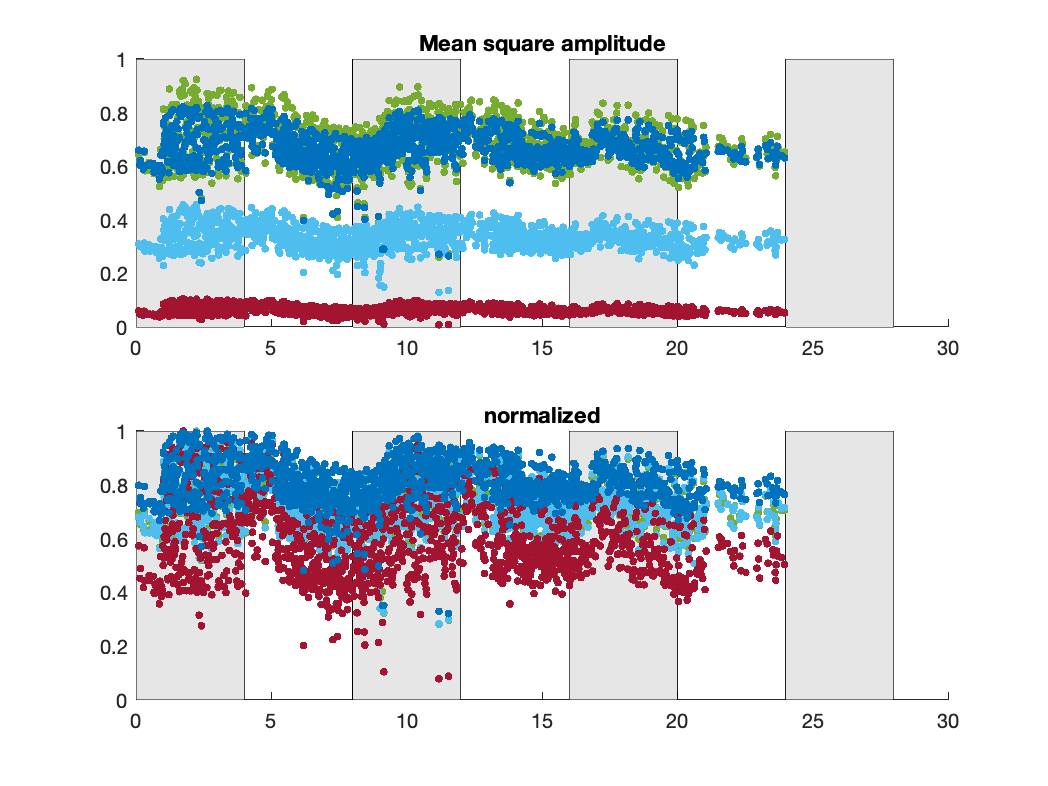

 %numbercycles = floor([out(1).s(datasubset(2)).timcont]/(4*60*60)); %number of cycles in data
        timz = 1:1:9;
      

lightlines = 0 + (4*(timz-1));


channel = 1;


figure(29);clf; hold on;
        
        ax(1) = subplot(211); title('Mean square amplitude');xlim([0 30]); hold on; 
           
%             plot([out(1).s.timcont]/3600, [out(1).s.psumfftAmp], '.', 'MarkerSize', 0.1);      
%             plot([out(1).s.timcont]/3600, [out(1).s.ppeakfftAmp], '.', 'MarkerSize', 0.1);
%             plot([out(1).s.timcont]/3600, [out(1).s.pobwAmp], '.', 'MarkerSize', 0.1);
%             plot([out(1).s.timcont]/3600, [out(1).s.zAmp], '.', 'MarkerSize', 0.1);
            a = [0 1];
            for j = 1:length(lightlines)-2
                if mod(j,2) == 1 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [0 a(2) a(2) 0], [0.9, 0.9, 0.9]);
                end
            end
            
            plot([out(2).s.timcont]/3600, [out(channel).s.psumfftAmp], '.', 'MarkerSize', 10);
            plot([out(2).s.timcont]/3600, [out(channel).s.ppeakfftAmp], '.', 'MarkerSize', 10);
            plot([out(2).s.timcont]/3600, [out(channel).s.pobwAmp], '.', 'MarkerSize', 10);
            plot([out(1).s.timcont]/3600, [out(1).s.pzAmp], '.', 'MarkerSize', 10);
         % legend('sumfftAmp', 'peakfftAmp', 'obwAmp', 'zAmp');

         ax(2) = subplot(212); title('normalized'); xlim([0 30]); hold on; 

            
            for j = 1:length(lightlines)-1
                if mod(j,2) == 1 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [0 a(2) a(2) 0], [0.9, 0.9, 0.9]);
                end
            end
        
            plot([out(1).s.timcont]/3600, [out(channel).s.psumfftAmp]/max([out(channel).s.psumfftAmp]), '.', 'MarkerSize', 10);
            plot([out(1).s.timcont]/3600, [out(channel).s.ppeakfftAmp]/max([out(channel).s.ppeakfftAmp]), '.', 'MarkerSize', 10);
            plot([out(1).s.timcont]/3600, [out(channel).s.pobwAmp]/max([out(channel).s.pobwAmp]), '.', 'MarkerSize', 10);
            plot([out(1).s.timcont]/3600, [out(channel).s.pzAmp]/max([out(channel).s.pzAmp]), '.', 'MarkerSize', 10);
            %legend('sumfftAmp', 'peakfftAmp', 'obwAmp', 'zAmp');
    
     linkaxes(ax, 'x')

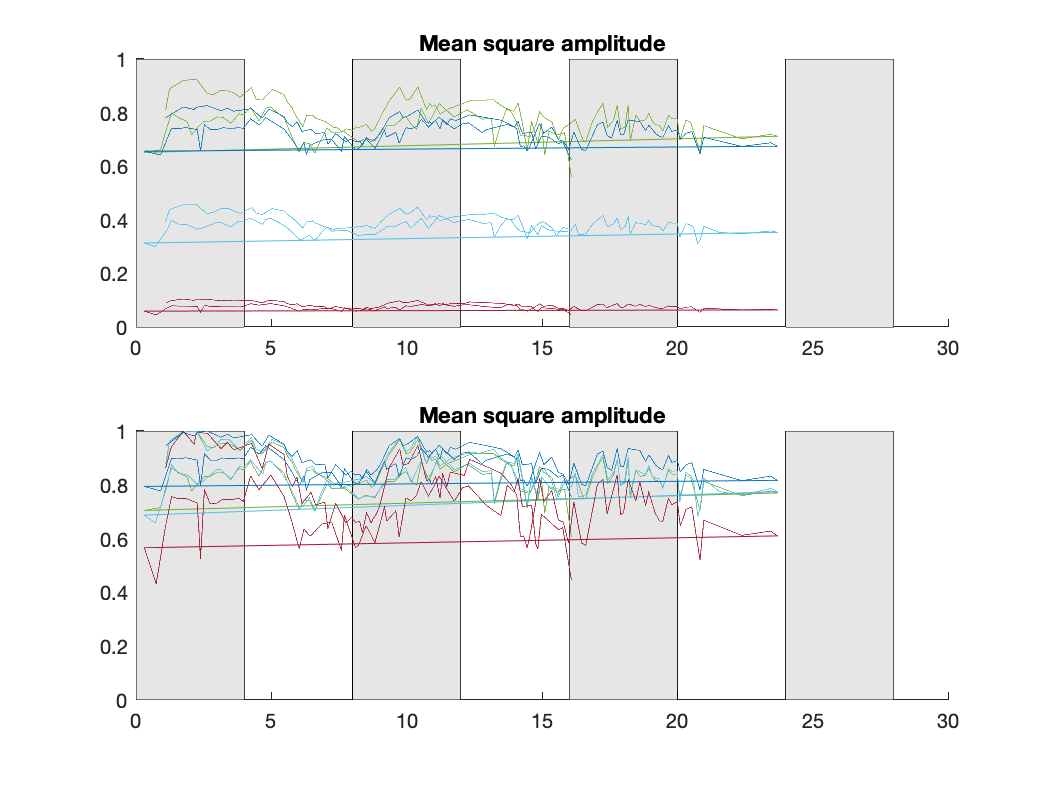


figure(30); clf; hold on;

         ax(1) = subplot(211); title('Mean square amplitude');hold on;

            for j = 1:length(lightlines)-1
                if mod(j,2) == 1 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [0 a(2) a(2) 0], [0.9, 0.9, 0.9]);
                end
            end
                [timcont, sumfftdata] = k_peaksofpeaksfilt([out(channel).s.timcont], [out(channel).s.psumfftAmp], 20);
                    plot(timcont/3600, sumfftdata);

                [timcont, peakfftdata] = k_peaksofpeaksfilt([out(channel).s.timcont], [out(channel).s.ppeakfftAmp], 20);
                    plot(timcont/3600, peakfftdata);
            
                [timcont, obwdata] = k_peaksofpeaksfilt([out(channel).s.timcont], [out(channel).s.pobwAmp], 20);
                    plot(timcont/3600, obwdata);

                [timcont, zdata] = k_peaksofpeaksfilt([out(1).s.timcont], [out(1).s.pzAmp], 20);    
                    plot(timcont/3600, zdata);
            

         ax(2) = subplot(212); title('Mean square amplitude'); hold on;

            for j = 1:length(lightlines)-1
                if mod(j,2) == 1 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [0 a(2) a(2) 0], [0.9, 0.9, 0.9]);
                end
            end
                [timcont, sumfftdata] = k_peaksofpeaksfilt([out(1).s.timcont], [out(channel).s.psumfftAmp]/max([out(channel).s.psumfftAmp]), 20);
                    plot(timcont/3600, sumfftdata);

                [timcont, peakfftdata] = k_peaksofpeaksfilt([out(1).s.timcont], [out(channel).s.ppeakfftAmp]/max([out(channel).s.ppeakfftAmp]), 20);
                    plot(timcont/3600, peakfftdata);
            
                [timcont, obwdata] = k_peaksofpeaksfilt([out(1).s.timcont], [out(channel).s.pobwAmp]/max([out(channel).s.pobwAmp]), 20);
                    plot(timcont/3600, obwdata);

                [timcont, zdata] = k_peaksofpeaksfilt([out(1).s.timcont], [out(1).s.pzAmp]/max([out(1).s.pzAmp]), 20);    
                    plot(timcont/3600, zdata); 

## Plot obw windowing

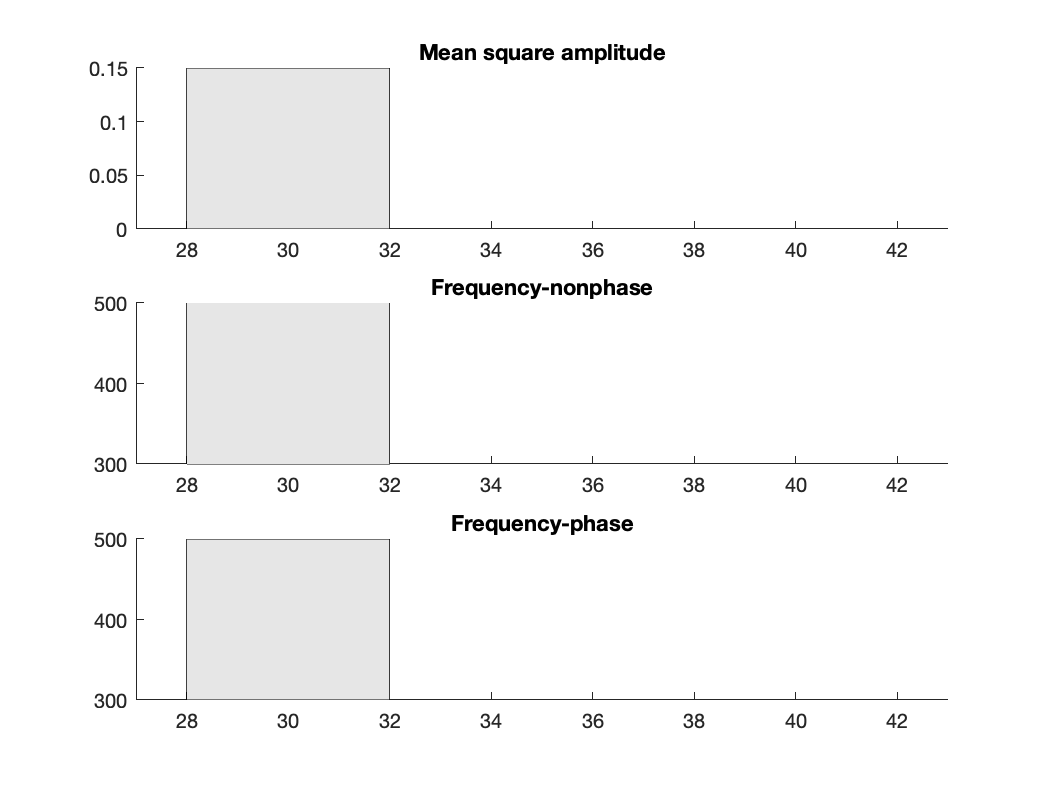

%coral
Coral = [255/255, 127/255, 80/255];
%Bluish green
Bluishgreen = [103/255, 189/255, 170/255];
ylw = [255/255 153/255 204/255];
%teal
teal = [0/255 114/255 178/255];

 %numbercycles = floor([out(1).s(datasubset(2)).timcont]/(4*60*60)); %number of cycles in data
        timz = 1:1:9;
      

lightlines = 0 + (4*(timz-1));

figure(28);clf; hold on;
        
        ax(1) = subplot(311); title('Mean square amplitude'); xlim([27 43]);hold on;
        plot([out(1).s.timcont]/3600, [out(1).s.sumfftAmp], '.', 'MarkerSize', 30,'Color', teal);
            plot([out(1).s.timcont]/3600, [out(1).s.obwAmp], '.', 'MarkerSize', 30,'Color', teal);
            a = ylim;
            for j = 1:length(lightlines)-1
                if mod(j,2) == 0 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [0 .15 .15 0], [0.9, 0.9, 0.9]);
                end
            end
            plot([out(1).s.timcont]/3600, [out(1).s.obwAmp], '.', 'MarkerSize', 30,'LineWidth', 1, 'Color',teal);
            plot([out(1).s.timcont]/3600, [out(1).s.pobwAmp], '.', 'MarkerSize', 10, 'Color',ylw);

            plot([out(1).s.timcont]/3600, [out(1).s.sumfftAmp], '.', 'MarkerSize', 30,'Color', 'b');
            plot([out(1).s.timcont]/3600, [out(1).s.sumfftAmp], '.', 'MarkerSize', 30,'LineWidth', 1, 'Color','r');
            
            
        
        ax(2) = subplot(312); title('Frequency-nonphase');xlim([27 43]); ylim([300 500]); hold on;

            plot([out(1).s.timcont]/3600, [out(1).s.flo]);
            plot([out(1).s.timcont]/3600, [out(1).s.fhi]);
            a = ylim;
            for j = 1:length(lightlines)-1
                if mod(j,2) == 0 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [a(1) 550 550 a(1)], [0.9, 0.9, 0.9]);
                end
            end

            patch([[out(1).s.timcont]/3600 fliplr([out(1).s.timcont]/3600)], [[out(1).s.flo] fliplr([out(1).s.fhi])],'b');
            plot([out(1).s.timcont]/3600, [out(1).s.fftFreq], 'k-', 'LineWidth', 2);
            
         ax(3) = subplot(313); title('Frequency-phase'); xlim([27 43]); ylim([300 500]);hold on;
            
            y1idx = find([out(1).s.pflo] > 385);

                x = [out(1).s.timcont]/3600;
                x = x(y1idx);
                y2 = [out(1).s.pflo];
                y2 = y2(y1idx);
                y1 = [out(1).s.pfhi];
                y1 = y1(y1idx);
                y3 = [out(1).s.fftFreq];
                y3 = y3(y1idx);
                
                plot(x, y1);
                plot(x, y2);
            

            a = ylim;
            for j = 1:length(lightlines)-1
                if mod(j,2) == 0 %if j is even
                fill([lightlines(j) lightlines(j) lightlines(j+1) lightlines(j+1)], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9]);
                end
            end
            patch([x fliplr(x)], [y1 fliplr(y2)],'r');
            plot(x,y3, 'k-', 'LineWidth', 2);
            
       
    
    linkaxes(ax, 'x')

## Go through individual samples and plot raw data

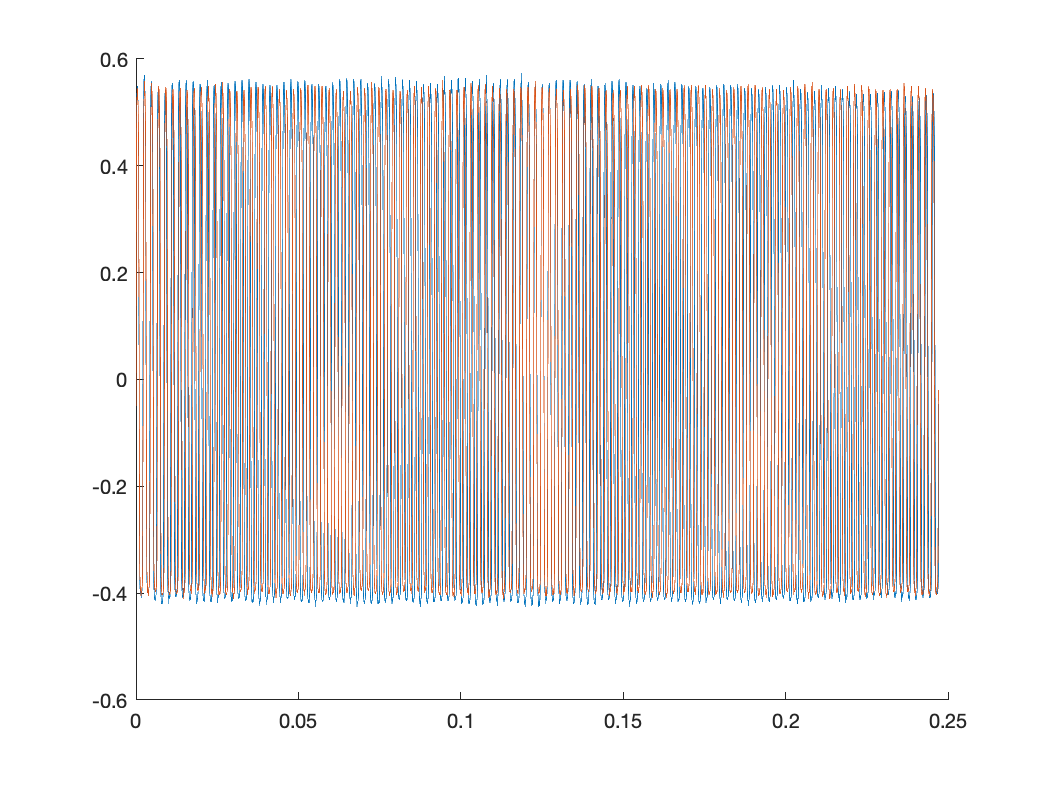

%% SET UP 
% Get the list of files to be analyzed  
        iFiles = dir(userfilespec);
        
        datasubset = [6950 7100];
        
       % iFiles = iFiles(datasubset);
            % Get sample frequency
            load(iFiles(1).name, 'tim');
            Fs = 1 / (tim(2) - tim(1));
            clear tim
               
% Set up filters
        % High pass filter cutoff frequency
            highp = 100; %200 %k = 9 800-1200
            [b,a] = butter(5, highp/(Fs/2), 'high'); % Filter to eliminate 60Hz contamination
        % Low pass filter cutoff frequency
            lowp = 1200;    %1500
            [f,e] = butter(5, lowp/(Fs/2), 'low'); % Filter to eliminate high frequency contamination
                    
% How much of the sample that we will use (each sample is 1 second)  
% This is important because the fish moves
        SampleWindw = 0.25; % 250 ms window
        %SampleWindw = 0.01;
% Fish limit frequencies for OBW calculation (unlikely to be changed)
        topFreqOBW = 700;%800
        botFreqOBW = 200;


%% CYCLE THROUGH EVERY FILE IN DIRECTORY

    ff = waitbar(0, 'Cycling through files.');

figure(25); clf ; hold on;

for kk = 1:length(datasubset)

     waitbar(kk/length(iFiles), ff, 'Assembling', 'modal');

       % LOAD THE DATA FILE
        load(iFiles(kk).name, 'data', 'tim');
        
        
       % Filter data  
          
            data(:,1) = filtfilt(b,a, data(:,1)); % High pass filter
           % data(:,1) = filtfilt(f,e, data(:,1)); % Low pass filter   
            
            data(:,2) = filtfilt(b,a, data(:,2)); % High pass filter
          %  data(:,2) = filtfilt(f,e, data(:,2)); % Low pass filter   
% 
        % Add time stamps (in seconds) relative to computer midnight (COMES FROM THE FILENAME)
 
                hour = str2double(iFiles(kk).name(numstart:numstart+1));        %numstart based on time stamp text location
                minute = str2double(iFiles(kk).name(numstart+3:numstart+4));
                second = str2double(iFiles(kk).name(numstart+6:numstart+7));
                
           
       % PICK YOUR WINDOW - THIS IS A CRITICAL STEP THAT MAY NEED REVISION

        for j = 1 %perform analyses on the first channels
        
            
            % FIND THE MAXIMUM
            [startim(kk), ~] = k_FindMaxWindow(data(:,j), tim, SampleWindw);

            data4analysis = (data(tim > startim(kk) & tim < startim(kk) + SampleWindw, j));     
            data4analysis = (data4analysis - mean(data4analysis)); 
                 timidx = find(tim > startim(kk) & tim < startim(kk)+SampleWindw);
                 nonphasetim = tim(timidx)-tim(timidx(1));  
            %find the first zero crossing
                    z = zeros(1,length(data4analysis)); %create vector length of data
                    z(data4analysis > 0) = 1; %fill with 1s for all filtered data greater than 0
                    z = diff(z); %subtract the X(2) - X(1) to find the positive zero crossings
                    posZs = find(z == 1); 
                    newidx = find(tim >= tim(posZs(1)) & tim <= tim(posZs(end)));

           phaseddata4analysis = data4analysis(newidx);
                    phasetim = tim(newidx)-tim(newidx(1));
                   
  plot(phasetim, phaseddata4analysis); 

           
        
        end
        
end


        pause(1); close(ff);

## Go through individual samples and plot raw data

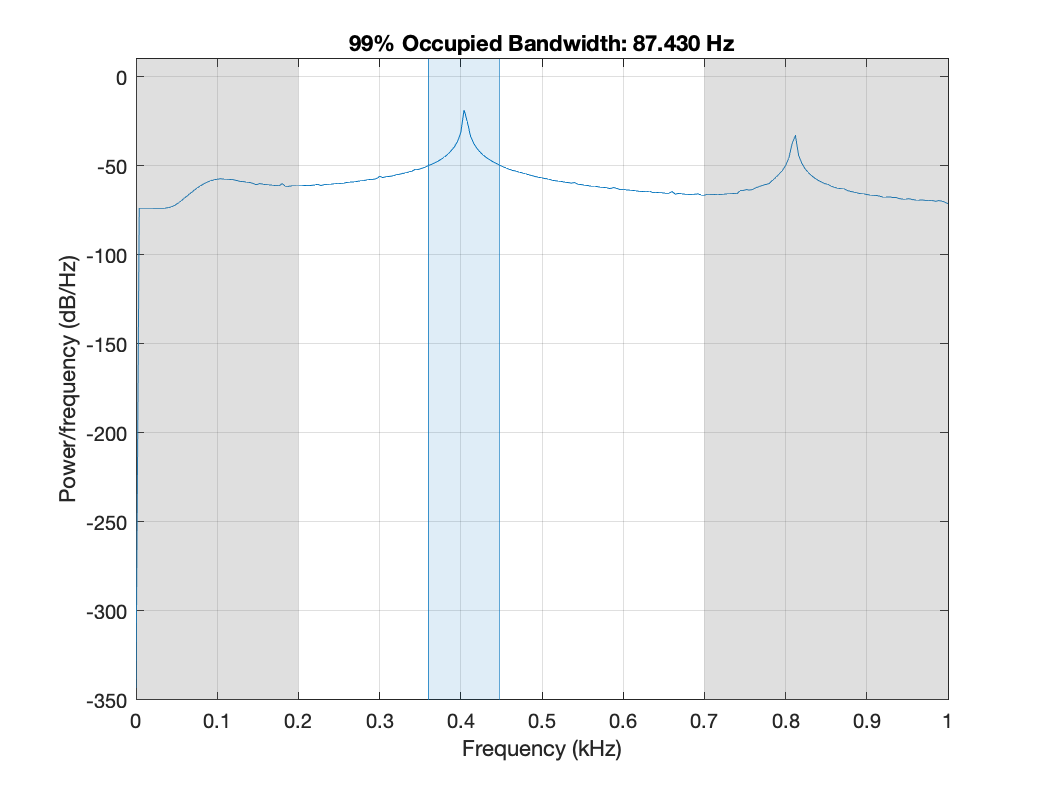

%% SET UP 
% Get the list of files to be analyzed  
        iFiles = dir(userfilespec);
        
        datasubset = [6955];% 7100];
        
        iFiles = iFiles(datasubset);
            % Get sample frequency
            load(iFiles(1).name, 'tim');
            Fs = 1 / (tim(2) - tim(1));
            clear tim
               
% Set up filters
        % High pass filter cutoff frequency
            highp = 100; %200 %k = 9 800-1200
            [b,a] = butter(5, highp/(Fs/2), 'high'); % Filter to eliminate 60Hz contamination
        % Low pass filter cutoff frequency
            lowp = 1200;    %1500
            [f,e] = butter(5, lowp/(Fs/2), 'low'); % Filter to eliminate high frequency contamination
                    
% How much of the sample that we will use (each sample is 1 second)  
% This is important because the fish moves
        SampleWindw = 0.25; % 250 ms window
        %SampleWindw = 0.01;
% Fish limit frequencies for OBW calculation (unlikely to be changed)
        topFreqOBW = 700;%800
        botFreqOBW = 200;


%% CYCLE THROUGH EVERY FILE IN DIRECTORY

    ff = waitbar(0, 'Cycling through files.');



for kk = 1:length(iFiles)
figure(89); clf ; hold on;
set(gcf,'renderer', 'zbuffer')
     waitbar(kk/length(iFiles), ff, 'Assembling', 'modal');

       % LOAD THE DATA FILE
        load(iFiles(kk).name, 'data', 'tim');
        
        
       % Filter data  
          
            data(:,1) = filtfilt(b,a, data(:,1)); % High pass filter
           % data(:,1) = filtfilt(f,e, data(:,1)); % Low pass filter   
            
            data(:,2) = filtfilt(b,a, data(:,2)); % High pass filter
          %  data(:,2) = filtfilt(f,e, data(:,2)); % Low pass filter   
% 
        % Add time stamps (in seconds) relative to computer midnight (COMES FROM THE FILENAME)
 
                hour = str2double(iFiles(kk).name(numstart:numstart+1));        %numstart based on time stamp text location
                minute = str2double(iFiles(kk).name(numstart+3:numstart+4));
                second = str2double(iFiles(kk).name(numstart+6:numstart+7));
                
           
       % PICK YOUR WINDOW - THIS IS A CRITICAL STEP THAT MAY NEED REVISION

        for j = 1 %perform analyses on the first channels
        
            
            % FIND THE MAXIMUM
            [startim(kk), ~] = k_FindMaxWindow(data(:,j), tim, SampleWindw);

            data4analysis = (data(tim > startim(kk) & tim < startim(kk) + SampleWindw, j));     
            data4analysis = (data4analysis - mean(data4analysis)); 
                 timidx = find(tim > startim(kk) & tim < startim(kk)+SampleWindw);
                 nonphasetim = tim(timidx)-tim(timidx(1));  
            %find the first zero crossing
                    z = zeros(1,length(data4analysis)); %create vector length of data
                    z(data4analysis > 0) = 1; %fill with 1s for all filtered data greater than 0
                    z = diff(z); %subtract the X(2) - X(1) to find the positive zero crossings
                    posZs = find(z == 1); 
                    newidx = find(tim >= tim(posZs(1)) & tim <= tim(posZs(end)));

           phaseddata4analysis = data4analysis(newidx);
                    phasetim = tim(newidx)-tim(newidx(1));
                   
            obw(data4analysis, Fs, [botFreqOBW topFreqOBW]); xlim([0,1]);
          %  obw(phaseddata4analysis, Fs, [botFreqOBW topFreqOBW]); xlim([0,1]);
           
        
        end
        
end


        pause(1); close(ff);

figure(1); clf;
set(gcf,'renderer', 'Painters')